# Título: **Cálculo de fuerzas internas en cables de sustentación vertical del puente colgante Golden Gate**

Tema del proyecto: **Modelo matemático para el cálculo de fuerzas internas en cables de sustentación vertical en puentes colgantes**

**Integrantes:**

- Integrante 1: ***Jordán O'Connor, Joaquín Francisco - 202110176 - participación 100% ***

- Integrante 2: ***Chachi Rodriguez, José Rafael - 202110069 - participación 100%***

- Integrante 3: ***Cernades Ames, Renato Aurelio - 202110068 - participación 100%***

- Integrante 4: ***Zúñiga Nole, Gilmar Gerard - 202020180 - participación 100%***

- Integrante 5:

**Datos adicionales:**

- Semestre: 2022-2

- Nombre del curso: Métodos Numéricos

- Docente: Molina Carabaño, Brigida Coromoto

- Sección: 3

- Número de grupo: 1

-----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## Resumen

(Opcional)

## Índice de contenido

# Introducción

## Tema del proyecto 

Los puentes colgantes han obtenido una gran reputación por su aspecto estético. Sin embargo, están en constante expansión, lo que lleva a la optimización del uso de materiales para reducir los costos finales del proyecto. Para este estudio se requiere mayor precisión en las técnicas analíticas para lograr una comprensión plena; al calcular las fuerzas internas de los cables verticales. Es una estructura que puede extenderse más de un kilómetro y que suele usarse para conectar dos puntos separados por agua, por ejemplo, el Golden Gate es un puente colgante ubicado en California, Estados Unidos. Tiene 6 caminos que cruzan el Canal Golden Gate y conectan la península de San Francisco a Marin. Su diseño es complejo, pues requiere la correcta distribución de la carga sobre los cables y los anclajes que los soportan (Zhang et al., 2018).

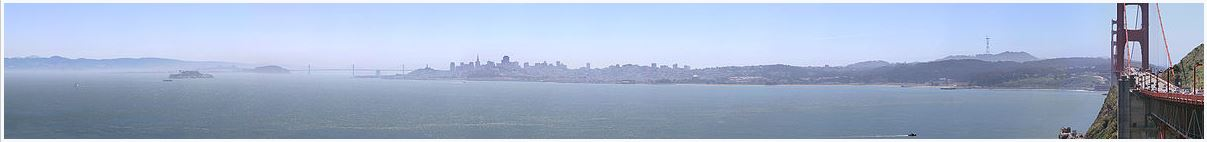

**Figura 1: **Vista panorámica de la bahía de San Francisco

Los puentes colgantes resisten diversas fuerzas: el peso del tráfico rodado y su propio peso. En la historia de estas construcciones se han producido derrumbamientos, debido a que el diseño no cumplía con las técnicas necesarias, como ejemplo, el puente Tacoma Narrows. Por ende, diseñar un puente colgante se deben tener en cuenta no solo el peso del puente y el tráfico rodado, sino todos los fenómenos atmosféricos que lo pueden afectar (movimiento sísmico, vientos y huracanes). Asimismo, la longitud del puente colgante se calcula en función de la distancia entre las dos torres que lo sostienen (Cáceres et al., 2021).

Hoy en día, la mayoría de los puentes colgantes están hechos de acero porque es un material resistente. Además de ello, se suelen utilizar sistemas de amortiguación para evitar posibles movimientos laterales. En este proyecto abordaremos la eficiencia de los métodos numéricos para el análisis estructural de las fuerzas internas mediante el uso de la ecuación de la catenaria.

## Identificación del problema

Las tensiones en los cables de sustentación vertical de un puente colgante no están uniformemente distribuidas en el estado final del puente, por lo que estas tensiones no son iguales a la carga muerta de la sección del puente entre dos cables adyacentes (Zhang et al., 2018).

Por lo tanto, se requieren de otros métodos para lograr un cálculo correcto de la tensión de los cables de sustentación vertical.

## Objetivos 

### Objetivo general 

Determinar el valor de la tensión en los cables de sustentación vertical del área principal del puente Golden Gate.

### Objetivos específicos

- Modelar el cable principal del puente Golden Gate como una serie de segmentos catenarios unidos.

- Calcular los parámetros de la ecuación catenaria mediante una aproximación parabólica.

- Hallar la tensión en los cables de sustentación vertical del área principal del puente.

- Comparar el valor hallado con lo propuesto por la literatura.

## Justificación

Actualmente, existe un gran interés en los puentes colgantes para la construcción de puentes largos, dado que optimizan la utilización de materiales sin sacrificar la integridad de la estructura (Zhang et al., 2017).

Por lo tanto, es necesario tener una medida precisa del valor de la tensión en los cables de sustentación vertical de los puentes colgantes, pues es un factor crítico para el equilibrio general de la estructura.

# Marco teórico 

## Antecedentes

*An iterative calculation method for hanger tensions and the cable shape of a suspension bridge based on the catenary theory and finite element method (Zhang et al., 2018): *A continuación se presenta el modelo matemático a utilizar. Este fue propuesto por Zhang et al. (2018).

Bajo la acción de las fuerzas concentradas/de bulto transferidas a través de las suspensiones, el cable en el estado final del puente está formado por muchos segmentos de catenaria colgados entre las suspensiones adyacentes. Cada segmento de cable y cada péndulo deben cumplir los siguientes requisitos subyacentes:

1. Los materiales trabajan en su rango elástico (es decir, por debajo de su nivel de tensión de fluencia), y sus dependencias de tensión-deformación siguen la ley de Hooke.

2. Se asumen las condiciones de deformación a pequeña escala, lo que implica que la deformación del cable es lo suficientemente pequeña como para no tener en cuenta la contracción transversal del cable.

3. El cable es idealmente flexible, lo que excluye la generación de tensiones de flexión en él.

La rigidez a la flexión del cable principal se desprecia por las siguientes dos razones (Zhang et al., 2018):

- Durante todo el proceso de construcción de un puente colgante, la rigidez a la flexión del cable principal es insignificante, al igual que el efecto de sujeción de una abrazadera sobre el cable principal.

- En los puentes colgantes de gran longitud, las abrazaderas ocupan un bajo porcentaje de la longitud total del cable principal en el vano central, alrededor del 6%.

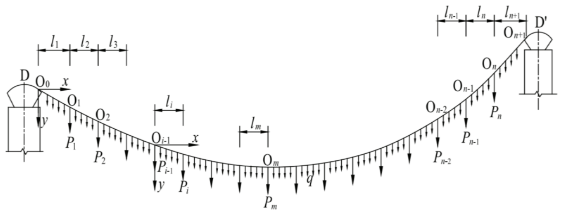

**Figura 2: **Configuración del cable en el estado de puente completado

En primer lugar, hay que realizar la búsqueda en el vano principal la forma que tiene el cable. Como podemos observar en la figura 2, se establecen varios sistemas de coordenadas, con su origen en el punto tangente izquierdo, $O_0$, y los puntos de suspensión, $O_1 -O_n$, a lo largo del cable, el eje x positivo apuntando hacia la derecha, y el eje y positivo apuntando hacia abajo. La forma de un segmento de cable arbitrario se deriva de la siguiente ecuación de catenaria: $y=c*cosh{\left(\frac{x}{c}+ai\right)}+bi\;\ldotp \ldotp \ldotp {\left(1\right)}$, donde $c = -\frac{H}{q}$, siendo q el peso del cable por unidad de longitud ($kN/m$) y H la componente horizontal de la tensión del cable en el estado de puente terminado ${\left(kN\right)}$; $a_i$ y $b_i$  son parámetros de la ecuación catenaria. A partir de la condición de frontera $y{\left(0\right)}=c*cosha_i +b_i =0$, se obtiene $b_i =-c*cosha_i$. Sustituyendo este término en la ecuación (1), puede reducirse a la siguiente forma: $y=c{\left[cosh{\left(\frac{x}{c}+a_i \right)}-cosha_i \right]}\dots {\left(2\right)}$.

Se introducen tres condiciones de restricción: 

1. La diferencia de cota entre el punto de la tangente izquierda y el punto medio del vano es cerrada $\overset{m}{\underset{i=1}{\Sigma}} \Delta h_i =\Delta h_{O_0 O_m }$.

2. La diferencia de elevación entre los dos puntos tangentes de los sillines izquierdo y derecho es cerrada $\overset{n+1}{\underset{i=1}{\Sigma}} \Delta h_i =\Delta h_{O_0 O_{n+1} } \ldotp$

3. La longitud de la proyección ortogonal del segmento de catenaria más a la derecha sobre el plano horizontal, $l_{n+1}$, cumple el siguiente diseño $l_{n+1} =l_{O_n D^{\prime } } -\Delta_2 \ldotp$

En las ecuaciones $m$ es el número de segmentos del cable entre el punto tangente izquierdo, $O_0$, y el punto intermedio, $O_m$; $n$ es el número de puntos de suspensión a lo largo del cable; ${\Delta h}_i$ denota la diferencia de elevación entre dos puntos extremos de un segmento catenario arbitrario del cable; $\Delta h_{O_0 O_m }$ es la diferencia de elevación entre el punto tangente izquierdo, $O_1$, y el punto intermedio, $O_m$; $\Delta h_{O_0 O_{n+1} }$ es la diferencia de elevación entre los puntos tangentes izquierdo ($O_0$) y derecho ($O_{n+1}$); $l_{O_n D^{\prime } }$ es la distancia horizontal diseñada entre la percha más a la derecha y el vértice real de la torre derecha, $D^{\prime }$, como se muestra en la **figura 3(b)**; $\Delta_2$ es la distancia horizontal entre los puntos $O_{n+1}$ y $D^{\prime }$, como se muestra en la **figura 3(b)**. Los tres parámetros desconocidos en las tres ecuaciones anteriores de catenaria son H, $a_i$ y $l_{\left(n+1\right)}$, que se refieren a la tensión horizontal del cable, al coeficiente de la ecuación de la catenaria para el primer segmento de la catenaria y a la longitud de la proyección ortogonal del segmento de la catenaria más a la derecha en el plano horizontal, respectivamente.

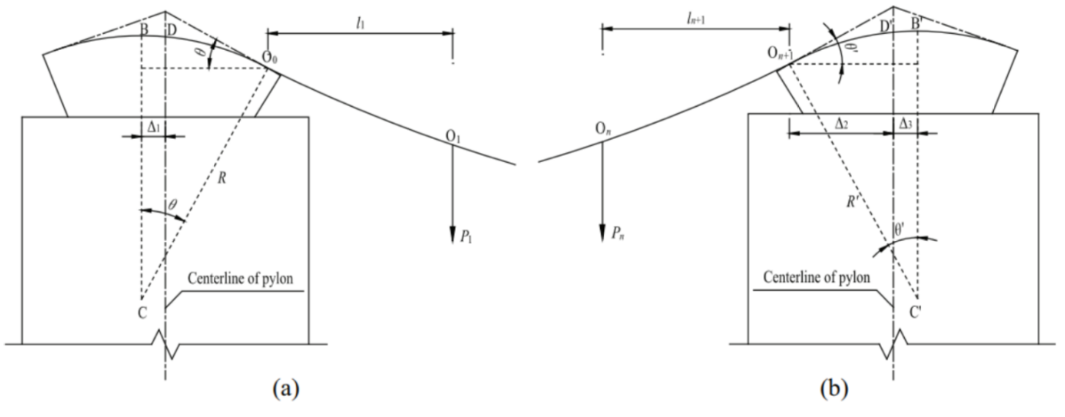 

**Figura 3: **Disposición de los sillines de la torre y parámetros críticos: (a) sillín de la torre izquierda y (b) sillín de la torre derecha

Luego de ello, podemos expresar todos los demás términos de las ecuaciones anteriores como funciones de estos tres parámetros. 

Así, $\Delta h_i$ puede expresarse como $\Delta h_i =y\left(l_i \right)-y\left(0\right)=c\left\lbrack \cosh \left(\frac{l_i }{c}+a_i \right)-\cosh \left(a_i \right)\right\rbrack$donde $l_i$ es la longitud de la proyección ortogonal de un segmento arbitrario de catenaria en el plano horizontal, como se muestra en la **figura 2**. Para una determinada elevación diseñada del centro del círculo, C, en el sistema geodésico (denotada como $h_C$), la elevación del punto tangente izquierdo en el sistema geodésico, $h_{O_0 }$ , puede escribirse como $h_{O_0 } =h_C +R*\cos \left(\theta \right)\ldotp \ldotp \ldotp \left(3\right)$, en donde R es el radio de la parte superior en forma de arco de la torre izquierda, como se muestra en la figura 3(a); $\theta$ es el ángulo entre el segmento vertical BC y el segmento que conecta el punto $O_0$ y el centro del círculo, C. En tanto $\tan \left(\theta \right)=\frac{d_y }{d_x }|_{x=0} =\sinh \left(a_1 \right)$, obtenemos $\cos \left(\theta \right)=\sech \left(a_1 \right)\ldotp \ldotp \ldotp \left(4\right)\ldotp$ La sustitución de la ecuación (4) en la ecuación (3) da como resultado $h_{O_0 } =h_C +R*\sech \left(a_1 \right)\ldotp$

Para una determinada elevación de diseño del punto $O_m$ en el sistema geodésico (denotada como $h_{O_m }$), la diferencia de elevación entre los puntos $O_0$ y $O_m$ (denotada como $\Delta h_{O_0 O_m }$) puede reducirse a  $\Delta h_{O_0 O_m } =h_{O_0 } -h_{O_m } =h_C +R*\sech \left(a_1 \right)-h_{O_m } \ldotp$

Para una elevación de diseño dada del centro del círculo, C', en el sistema geodésico, denotada como hC', la elevación del punto tangente derecho en el sistema geodésico, $h_{O_{n+1} }$, puede expresarse como $h_{O_{n+1} } =h_{C^{\prime } } +R^{\prime } *\cos \left(\theta^{\prime } \right)\ldotp \ldotp \ldotp \left(5\right)$, en donde $R^{\prime }$ es el radio de la parte superior en forma de arco de la torre derecha, como se muestra en la figura 3(a); $\theta^{\prime }$ es el ángulo entre el segmento vertical B'C' y el segmento que conecta el punto $O_{n+1}$ y el centro del círculo, C.' 

De forma similar, de la ecuación $\tan \left(\theta^{\prime } \right)=-\frac{d_y }{d_x }|_{x=l_{n+1} } =-\sinh \left(\frac{l_{n+1} }{c}+a_{n+1} \right)$se obtienen $\cos \left(\theta^{\prime } \right)=\sech \left(\frac{l_{n+1} }{c}+a_{n+1} \right)\ldotp \ldotp \ldotp \left(6\right)$y $\textrm{sen}\left(\theta^{\prime } \right)=\sech \left(\frac{l_{n+1} }{c}+a_{n+1} \right)$

La sustitución de la ecuación (6) en la ecuación (5) da como resultado $h_{O_{n+1} } =h_{C^{\prime } } +R^{\prime } *\sech \left(\frac{l_{n+1} }{c}+a_{n+1} \right)$. Entonces, la diferencia de elevación entre los puntos $O_0$ y $O_{n+1}$, denominada $\Delta h_{O_0 O_{n+1} }$ , puede expresarse así $\Delta h_{O_0 O_{n+1} } =h_{O_0 } -h_{O_{n+1} } =h_C {-h}_{C^{\prime } } +R*\sech \left(a_1 \right)-R^{\prime } *\sech \left(\frac{l_{n+1} }{c}+a_{n+1} \right)$. La expresión para $\Delta_2$ es $\Delta_2 =R^{\prime } *\textrm{sen}\left(\theta^{\prime } \right)-\Delta_3 =-R^{\prime } *\tanh \left(\frac{l_{n+1} }{c}+a_{n+1} \right)$$-\Delta_3$. Donde D3 es la distancia horizontal entre los puntos C' y D', como se muestra en la figura 3(b).

En un punto de suspensión arbitrario del cable principal, la fuerza de tracción axial puede descomponerse en una componente vertical y otra horizontal, como podemos observar en la** figura 4 **(Zhang et al., 2018). A partir de la condición de equilibrio de fuerzas en la dirección vertical, podemos obtener: $Htan\varphi_i =Htan\varphi_{i+1} +P_i \;\ldotp \ldotp \ldotp \left(7\right)$ 

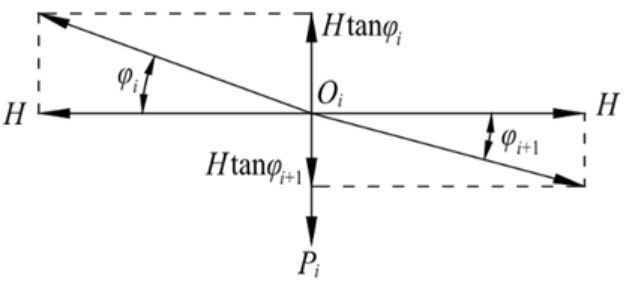

**Figura 4:** Diagrama de cuerpo libre de las fuerzas en un punto de suspensión *Oi*

Donde $li$ es la longitud de la proyección ortogonal de un segmento arbitrario de catenaria en el plano horizontal, como podemos observar en la figura 2, $P_i$ es la fuerza de tracción de la suspensión y $\varphi_i$ y $\varphi_{i+1}$ son los ángulos de inclinación para los segmentos de cable a la derecha y a la izquierda del de suspensión, $O_i$, respectivamente. Al sustituir $tan{\left(\varphi_i \right)}=sinh{\left(\frac{l_i }{c}+a_i \right)}$y $tan{\left(\varphi_{i+1} \right)}=sinh{\left(a_{i+1} \right)}$ en la ecuación (7), obtenemos: $Hsinh{\left(\frac{l_i }{c}+a_i \right)}=Hsinh\left(a_{i+1} \right)+P_i \;$. Reordenando los términos, obtenemos $\left.P_i \;=H\left(sinh{\left(\frac{l_i }{c}+a_i \right)}-sinh\left(a_{i+1} \right)\right)$.

## Conceptos clave 

### Partes de un puente colgante

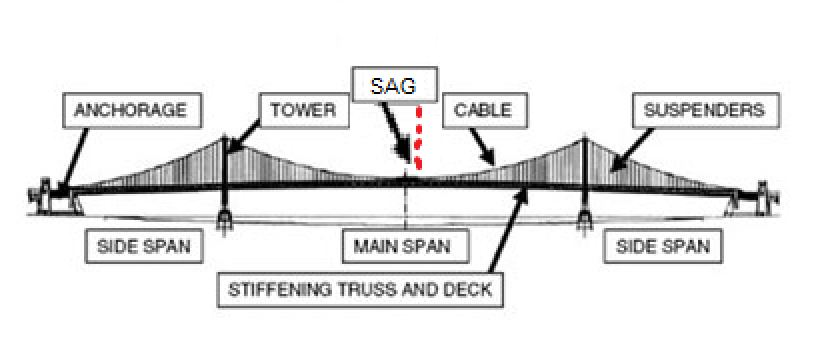

**Figura 5:** Nombres de algunas partes de un puente colgante en inglés

**Método analítico: **Es un procedimiento que descompone un todo en sus elementos básicos y, por tanto, que va de lo general a lo específico.

**Fuerzas concentradas: **Una fuerza concentrada representa el efecto de una carga que se supone actúa en cierto punto de un cuerpo.

**Catenaria: **En física y geometría, una catenaria es la curva que una cadena o cable colgante idealizado asume bajo su propio peso cuando se apoya sólo en sus extremos en un campo gravitatorio uniforme. La curva catenaria tiene una forma de U, superficialmente similar en apariencia a un arco parabólico, pero no es una parábola.

**Cables de sustentación vertical: **Cables situados en el plano de un entramado transversal que transmiten las cargas debidas a la gravedad a la parte superior del casco.

**Rango elástico: **El límite elástico o límite de elasticidad es la tensión máxima que un material elastoplástico puede soportar sin sufrir deformaciones permanentes.

**Ley de Hooke:**  La deformación elástica que sufre un cuerpo es proporcional a la fuerza que produce tal deformación, siempre y cuando no se sobrepase el límite de elasticidad.

**Contracción transversal:**Disminución de la sección del elemento estirado.

**Proyección ortogonal: **Una proyección ortogonal es aquella que se crea a partir del trazado de la totalidad de las rectas proyectantes perpendiculares a un cierto plano.

**Fuerza de tracción axial: **En el cálculo de estructuras e ingeniería se denomina fuerza de tracción a las fuerzas externas actúan tratando de "estirar" el cuerpo, intentando producir un alargamiento del mismo.

**Rigidez: **Propiedad extensiva que mide la capacidad de un cuerpo de resistir deformación, es una medida de la resistencia a las deformaciones elásticas producidas por un material. Depende del módulo de elasticidad y específicamente se habla de rigidez en tracción.

**Flexibilidad: **Es la inversa de la rigidez. Cuanto más rígido, menos flexible.

**Esfuerzo (stress):** Es la fuerza sobre la unidad de área perpendicular a dicha fuerza.

**Esfuerzo de tracción: **La tracción es el esfuerzo al que está sometido un cuerpo por la aplicación de dos fuerzas que actúan en sentido opuesto, y tienden a estirarlo.

**Módulo de elasticidad: **Es una propiedad intensiva del material

**Deformación unitaria:** La deformación unitaria (δ) se define como el cambio de longitud, por unidad de longitud, debido a una carga normal sobre un material. Esta se puede relacionar directamente con el esfuerzo generado sobre el material al dividir la carga que genera la deformación entre el área transversal del material.

**Tensión o límite de fluencia: **En ciencia e ingeniería de materiales, el punto de fluencia es el punto en una curva de tensión-deformación que indica el límite del comportamiento elástico y el comienzo del comportamiento plástico. Por debajo del límite elástico, un material se deforma elásticamente y volverá a su forma original cuando se elimine la tensión aplicada.

**Esfuerzo de fluencia: **Indicación del esfuerzo máximo que se puede desarrollar en un material sin causar una deformación plástica. Es el esfuerzo en el que un material exhibe una deformación permanente especificada y es una aproximación práctica de límite elástico.

### Métodos iterativos

*Los métodos iterativos para ecuaciones no lineales:* El estudio de los métodos iterativos para ecuaciones no lineal es de gran importancia ya que son nuestra única herramienta para resolver estos tipos de problemas, además, necesitamos que estos métodos sean lo más precisos y rápidos posibles, dada la alta complejidad de los problemas en el mundo real. A continuación se explican los métodos para hallar las raíces de ecuaciones no lineales y sus criterios de convergencia para, posteriormente, comparar los resultados hallados en este proyecto con la literatura.

#### Método de la bisección

El método de la bisección busca hallar las raíces de una función $f(x)$ en base a un intervalo. Este es un método cerrado ya que siempre podemos encontrar una raíz siempre cuando la función sea continua. Este método consiste en ir partiendo un intervalo a la mitad siguiendo las reglas que mostraremos a continuación (Chapra & Canales, 1999).

Este método se desarrolla de la siguiente forma:

Dado un intervalo $[a, b]$ y una función $ f(x)$.

- Verificar si existe un cambio de signo en la función f en el intervalo [a, b]. Para esto evaluamos $f(a)\cdot(b)<0$. Si dicha condición es verdadera, continuamos, caso contrario, no existe raíz en nuestro en el intervalo $[a, b]$.

- Se toma un punto medio $c$ del intevalo, es decir, $c=\frac{a+b}{2}$ y se evalua $f(a)\cdot(c) >0$. Si es verdad, se remplaza $a$ por $c$ y volvemos al paso 1. Caso contrario, se evalua $f(c)\cdot(b)>0$ y si es cierto se remplaza $b$ por $c$ y volvemoms al paso 1.

Todo este procedimiento se repetira según el número de iteraciones que el matemático considere o según una toleración dada por la siguiente ecuación:

$n \ge \frac{\ln(\frac{b-a}{2\cdot Tol})}{\ln2}$, donde n es el menor valor entero que cumpla dicha desigualdad.

**Demostración**

Este método funciona ya que partimos de un intervalo $[a, b]$ donde $f(a)\cdot f(b) < 0$; gracias al requisito de $f(x)$ de ser una función continua, podemos asegurar que al haber un cambio de signo en la función para dicho intevalo, en algún punto este se intersecta con el eje x, por consecuente, encontraremos una raíz en dicho intervalo (Chapra & Canale, 1999).

#### Método de Newton-Raphson

El método de Newton-Raphson es un método iterativo que busca hallar las raíces de una función a partir de un iterador inicial. Por lo general, es un método que converge rápidamente, sin embargo, es un método abierto por lo que no encierra necesariamente a la raíz y en algunos casos pueden diverger (Chapra & Canale, 1999).

El método se desarrolla de la siguiente forma:

Dado un iterador incial $x_o$ y una función $f(x)$. Se calcula la siguiente aproximación a de la raíz como $x_{i+1}=x_i-\frac{f(x_i)}{f'(x_i)}$ y luego se vuelve a iterar siendo $x_i = x_{i+1}$.

**Deducción**

Deduciremos la fórmula del método a partir de la serie de Taylor.

Por la serie de Taylor podemos representar una función como: $f(x_{i+1}) = f(x_i)+f'(x_i)(x_{i+1}-x_i)+\frac{f''(\xi)(x_{i+1}-x_i)^2}{2!}$ , donde $\xi \in [x_i, x_{i+1}]$ (Ecuación 1)

Y truncando la serie hasta el 2do término tenemos:

$f(x_{i+1}) = f(x_i)+f'(x_i)(x_{i+1}-x_i)$  (Ecuación 2)

Para hallar las raíces, la intersección con el eje x debe ser cero. Por lo que tenemos:

$0 = f(x_i)+f'(x_i)(x_{i+1}-x_i)$  (Ecuación 3)

Y despejando $x_{i+1}$ nos queda:


$$-f'(x_i)(x_{i+1})=f(x_i) - f'(x_i)(x_i)$$



$$x_{i+1}=\frac{f(x_i) - f'(x_i)(x_i)}{-f'(x_i)}$$


$x_{i+1}= x_i - \frac{f(x_i)}{f'(x_i)}$  (Ecuación 4)

Así deducimos la fórmula de Newton-Raphson.  De la misma forma podemos deducir el error del método remplazando $x_{i+1} = x_r$, donde suponemos que $x_r$ es el valor real de la raíz, en la ecuación 1 y sustituyendo $f(x_r)=0$ nos queda:

$0 = f(x_i)+f'(x_i)(x_{r}-x_i)+\frac{f''(\xi)(x_{r}-x_i)^2}{2!}$ (Ecuación 5)

Se resta la ecuación 5 con la 3 y obtenemos que el error es:

$0 = f'(x_i)(x_{r}-x_{i+1})+\frac{f''(\xi)(x_{r}-x_i)^2}{2!}$ (Ecuación 6)

Note que el error es la diferencia entre $x_{i+1}$ y el valor $x_r$, entonces la ecuación 6 se puede expresar como:

$0=f'(x_i)E_{i+1}+\frac{f''(\xi)E^2_i}{2!}$, siendo $E = x_{r}-x_{x+1}$. (Ecuación 7)

Suponiendo hay convergencia, $x_i$ y $\xi
$deben acercarce a la raíz de la función, entonces la ecuación 7 se puede expresar como:


$$E_{i+1}=-\frac{f''(x_r)E^2_i}{2f'(x_r)}$$


Y está ecuación nos dice que el error $E_{i+1}$ está en proporción cuadrática al error anterior $E_i$. Lo que significa que este método tienen una convergencia cuadrática, por lo que cada iteración duplicara el número de cifras significativas.

**Convergencia**

No existe realmente un críterio general de convergencia para este método, ya que existen funciones que ningún iterador incial les es útil; por lo que se dice que el críterio de convergencia depende de la naturaleza de la función y la calidad del iterador inicial (Chapra & Canale, 1999).

#### Método del Punto Fijo

Este método se basa, como su nombre lo dice, en iterar sobre un punto fijo x, el cual se obtiene al despejar x de una función $f(x)$. Este es un método abierto, lo que quiere que no encerramos la raíz en todo momento, de tal forma que en ciertos casos el método puede diverger (Chapra & Canale, 1999).

**Desarrollo del método**

Sea la función $f(x)$ despejamos x y tendrémos $x = g(x)$. Luego nuestra aproximación está dada por $x_{i+1}=g(x_i)$ y repetimos el proceso hasta cumplir un cierto número de iteración o una tolerancia dada.

El error en este caso está dado por $\epsilon_a=|\frac{x_{i+1}-x_i}{x_{i+1}}|$

**Convergencia y análisis**

Este método requiere de ciertos criterios para converger. Dado $a, b \in \mathbb{R}$ talque a < b y g :  $[a, b] \to \mathbb{R}$ una función continua en $[a, b]$ y derivable en $]a, b[$.

- 
$$|g'(x)| < 1, \forall \ x \in \ ]a,b[ $$


- 
$$\forall \ x \in \ [a, b], \ g(x) \in [a,b]$$


Entonces existe un único punto tal que g(p) = p. Entonces al construir una sucesión de la forma $x_{k+1}=g(x_k)$, esta converge al punto fijo p de la función (Chapra & Canales, 1999).

# Metodología 

## Modelo matemático

### Métodos de resolución

#### Interpolación de funciones

- Interpolación polinomial: Se utilizará para aproximar las catenarias sucesivas como un polinomio de grado 2 (parábola).

  
$$\begin{array}{l}
y\left(l_i \right)=-\frac{H}{w}\left\lbrack \cosh \left(-\frac{w}{H}*l_i +a_i \right)-\cosh \left(a_i \right)\right\rbrack \\
P_i =H\left\lbrack \textrm{senh}\left(-\frac{w}{H}*l_i +a_i \right)-\textrm{senh}\left(a_{i+1} \right)\right\rbrack 
\end{array}$$


### Ecuaciones no lineales - Métodos iterativos    

- Método de la bisección: Es un método cerrado que se utilizará para hallar los coeficientes y que nos permitirá hacer un cálculo preciso.

- Método de Newton: Es un método abierto que se utilizará para hallar otra aproximación de los coeficientes y se espera que el cálculo sea de mayor precisión que el de la bisección. 

## Datos

**Zona de estudio**

El puente Golden Gate está ubicado en la bahía de San Francisco, California, Estados Unidos. En la bahía se encuentran los ríos Sacramento, San Joaquin, Petaluma, Napa y Guadalupe, además parte del Oceáno Pacífico.

**Periodo de estudio:** **Periodo histórico (1940-1982) y Periodo futuro (2000-2023)**

Luego del colapso del puente de Tacoma Narrows en el año 1940, la Encuesta geodésica nacional de EE.UU. decidió mandar un equipo de investigación a nivel nacional para calcular los movimientos verticales de todos los puentes colgantes. Es a mediados del año 1982 que se logró realizar un estudio al puente Golden Gate que estableció un comportamiento segurido a las vibraciones que este mismo posee. Actualmente, la investigación realizada nos entrega una tabla de datos en donde nos muestran las propiedades estructurales del puente. En un futuro se espera realizar simulaciones para determinar el comportamiento del puente en posibles casos sísmicos u otros similares.

**Variables de estudio**

Para establecer el dinanismo del puente se decidió analizar principalmente el comportamiento de los cables que lo sostienen. Para ello se utilizó las fuerzas horizontales, pesos, longitud y las distancias entre los distintos cables verticales. Utilizamos la longitud en metros y la fuerza en Newtons.

**Recopilación/obtención de datos**

Los datos obtenidos es sobre un estudio de las vibración que posee el puente colgante Golden Bridge de un equipo de investigación de la Sociedad Estadounidense de Ingenieros Civiles, sus siglas en inglés como ASCE. 

**Tabla de datos**

  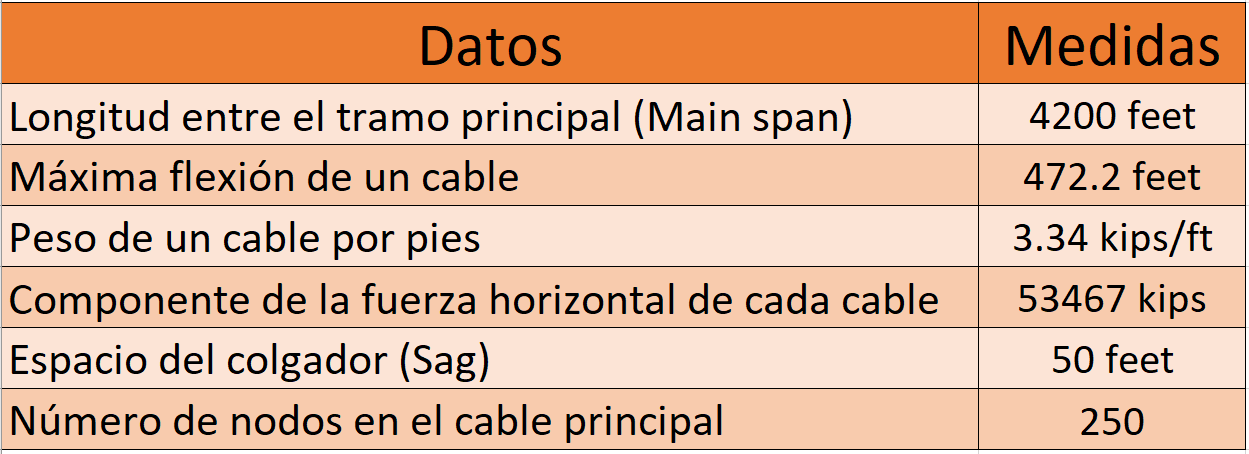

**Tabla 1:** Ciertos datos extraídos del anexo 1 para las operaciones

La tabla de datos nos enseñan otras medidas que fueron utilizadas en el estudio de la NGS. Por el otro lado, las unidades que emplearon son del sistema imperial: *feet (ft), inches (in) y kips*.

format long
% Número de nodos en el cable principal
N = 250

N =    250


% Separación horizontal de los cables verticales (ft)
li = 50

li =     50


% Maxima distancia entre el punto más bajo y más alto del cable principal
MAX_CABLE_SAG = 472.2

MAX_CABLE_SAG =      4.722000000000000e+02


% Longitud del cable principal
LENGTH_MAIN_SPAN = 4200

LENGTH_MAIN_SPAN =         4200


% Fueza horizontal de cada cable (kips)
H = 53467

H =        53467


% Peso de cable por unidad de longitud (kips/ft)
W = 3.34

W =    3.340000000000000


# Desarrollo

## Resultados

### Objetivo 1

Para cumplir con el objetivo 1 de modelar el cable principal del puente Golden Gate como una serie de segmentos catenarios unidos, necesitamos utilizar los resultados del objetivo 2 de calcular los parámetros de la ecuación catenaria mediante una aproximación parabólica. A continuación se realiza dicha aproximación, utilizando los datos para el cable principal. El sistema de coordenadas está posicionado según la siguiente figura:

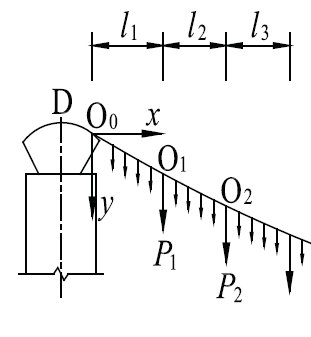

**Figura 6: **Representación gráfica de los cables (*Oi* es un cable vertical)

x = [0 LENGTH_MAIN_SPAN/2 LENGTH_MAIN_SPAN];
y = [0 MAX_CABLE_SAG 0];
p2 = polyfit(x, y, 2)

p2 =   -0.000107074829932   0.449714285714286   0.000000000000091


Graficamos la aproximación obtenida. Note que el sistema de coordenadas planteado tiene la coordenada y hacia abajo.

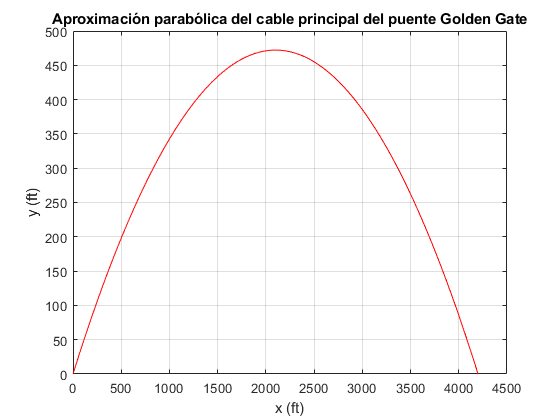

xx = linspace(x(1), x(end));
plot(xx, polyval(p2, xx), "r")
title("Aproximación parabólica del cable principal del puente Golden Gate")
xlabel("x (ft)")
ylabel("y (ft)")
grid on

Con estos datos, ya podemos estimar la diferencia de altura entre los nodos $O_0$ y $O_1$ de la siguiente manera.

yl1 = abs(polyval(p2, 0) - polyval(p2, li));

A su vez, tambien hallaremos la diferencia de altura entre los nodos $O_1$ y $O_2$.

yl2 = abs(polyval(p2, li) - polyval(p2, 2*li));

Con esta información, ya podemos utilizar la ecuación que modela el cable como una serie de segmentos catenarios unidos. Estimaremos sus parámetros, pues estos serán necesarios para cumplir nuestro tercer objetivo.

### Objetivo 2

Hallaremos los parámetros del primer segmento catenario, que nos permitirán hallar posteriormente el valor de la tensión del cable de sustentación vertical unido al punto de suspensión $O_1$ ($P_1$). Note que según los datos de Abdel-Ghaffa & Scanlan (1985), $P_i$ es constante para todos los nodos $O_i$. Por lo tanto, basta con hallar $P_1$ para hallar $P_i$. Con los parámetros de la ecuación de la catenaria $a_1$ y $a_2$ podemos hallar $P_i$. Los problemas a resolver para hallar dichos parámetros son un conjunto de ecuaciones no lineales. Para resolverlas, utilizaremos los tres métodos planteados en el modelamiento matemático: Método de la Bisección, Método de Newton-Raphson y Método del Punto Fijo.

Primero, planteamos las ecuaciones no lineales a resolver, que corresponden a la ecuación de los segmentos catenarios entre $O_0$ y $O_1$ y $O_1$ y $O_2$.

f1 = @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl1);
f2 = @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2);

Planteadas las ecuaciones en forma de funciones, se procede con su resolución mediante los tres métodos.

#### Método de la Bisección

Al ser un método cerrado, primero tenemos que encontrar el intervalo en el que se encuentra nuestra raíz. Como primera aproximación para el intervalo, se prueba [0.3,0.6], pues en el trabajo de Cáceres et al. (2021) se encontró los valores en este rango. Graficaremos las funciones en este intervalo y verificaremos nuestra suposición.

a = 0.3;
b = 0.6;
xx = linspace(a, b);
yy = f1(xx);
yy2 = f2(xx);
plot(xx, yy, 'g', xx, yy2, 'm', xx, zeros(length(xx)), 'k')
xlabel("a")
ylabel("f")
title("Raíces de f1 y f2")
legend("f1", "f2", "y=0")
grid on
hold off

Como se observa, podemos encontrar las raíces de ambas ecuaciones en el intervalo [0.4, 0.45].

a = 0.4; b = 0.45;

Con esta información, se calculan los valores de $a_1$ y $a_2$. Se utilizarán 30 iteraciones, o una tolerancia de ${10}^{-8}$, lo que ocurra antes y considerando que los cálculos son computacionalmente poco complejos.

tol = 1e-8; maxiter = 30;

**Aproximación de **$a_1$

[a1Biseccion, R1Biseccion] = biseccion(f1, a, b, tol, maxiter)

a1Biseccion =    0.432463055849075


R1Biseccion = 23×8 table
    Iteration            a                    b                    c                    f(a)                     f(b)                    f(c)                      Ea         
    _________    _________________    _________________    _________________    _____________________    ____________________    _____________________    ____________________

        0                      0.4                 0.45                0.425        -1.76479372468048       0.962985367072921       -0.407720254721564                   0.025
        1                    0.425                 0.45               0.4375       -0.407720254721564       0.962985367072921        0.275875197167743                  0.0125
  

**Aproximación de **$a_2$

[a2Biseccion, R2Biseccion] = biseccion(f2, a, b, tol, maxiter)

a2Biseccion =    0.422658771276474


R2Biseccion = 23×8 table
    Iteration            a                    b                    c                    f(a)                     f(b)                    f(c)                      Ea         
    _________    _________________    _________________    _________________    _____________________    ____________________    _____________________    ____________________

        0                      0.4                 0.45                0.425        -1.22941957502061        1.49835951673279        0.127653894938302                   0.025
        1                      0.4                0.425               0.4125        -1.22941957502061       0.127653894938302       -0.552533652115571                  0.0125
  

**Aproximación de **$P_i$

PiBiseccion = H*(sinh((-W/H)*0 + a1Biseccion) - sinh(a2Biseccion))

PiBiseccion =      5.728569562310826e+02


#### Método de Newton-Raphson

Haremos el mismo cálculo utilizando el método de Newton-Raphson con un valor inicial de 0.4, pues ya sabemos que la solución está próxima a este valor. Se utilizará la misma tolerancia y número de iteraciones que para el Método de la Bisección.

x0 = 0.4;

**Aproximación de **$a_1$

[a1NewtonRaphson, R1NewtonRaphson] = newtonraphson(f1, x0, tol, maxiter)

a1NewtonRaphson =    0.432463058418837


R1NewtonRaphson = 5×3 table
    Iteration           x*                     Er         
    _________    _________________    ____________________

        0                      0.4                       1
        1        0.432668278217765                       1
        2        0.432463066971984      0.0755042138802758
        3        0.432463058418861    0.000474517389929587
        4        0.432463058418837    1.97776974847866e-08


**Aproximación de **$a_2$

[a2NewtonRaphson, R2NewtonRaphson] = newtonraphson(f2, x0, tol, maxiter)

a2NewtonRaphson =    0.422658775643757


R2NewtonRaphson = 4×3 table
    Iteration           x*                     Er         
    _________    _________________    ____________________

        0                      0.4                       1
        1        0.422757912248589                       1
        2        0.422658777599001      0.0538320196718336
        3        0.422658775643757    0.000234550078794016


**Aproximación de **$P_i$

PiNewtonRaphson = H*(sinh((-W/H)*0 + a1NewtonRaphson) - sinh(a2NewtonRaphson))

PiNewtonRaphson =      5.728568520037547e+02


#### Método del Punto Fijo

Para la aplicación de este método iterativo, se considerara el siguiente despeje:


$$\begin{array}{l}
y\left(l_i \right)=-\frac{H}{w}\left\lbrack \cosh \left(-\frac{w}{H}*l_i +a_i \right)-\cosh \left(a_i \right)\right\rbrack \\
-\frac{w}{H}*y\left(l_i \right)=\cosh \left(-\frac{w}{H}*l_i +a_i \right)-\cosh \left(a_i \right)\\
\cosh \left(a_i \right)=\cosh \left(-\frac{w}{H}*l_i +a_i \right)+\frac{w}{H}*y\left(l_i \right)\\
a_i =\cosh^{-1} \left(\cosh \left(-\frac{w}{H}*l_i +a_i \right)+\frac{w}{H}*y\left(l_i \right)\right)
\end{array}$$


Donde $x=a_i$ para las funciones planteadas a continuación.

g1 = @(x) (acosh(cosh((-W/H)*li+x)+(W/H)*yl1));
g2 = @(x) (acosh(cosh((-W/H)*li+x)+(W/H)*yl2));

Primero, evaluaremos su convergencia. El intervalo escogido será el mismo que se utilizó para el Método de la Bisección.

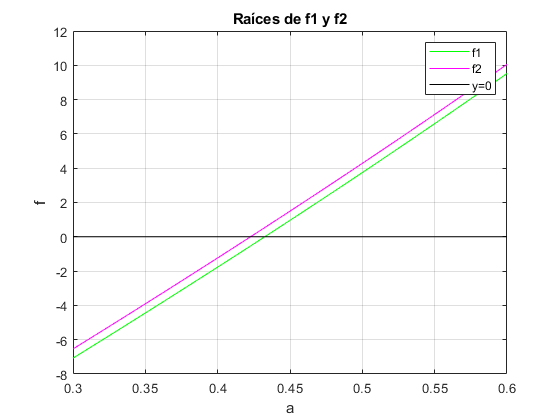

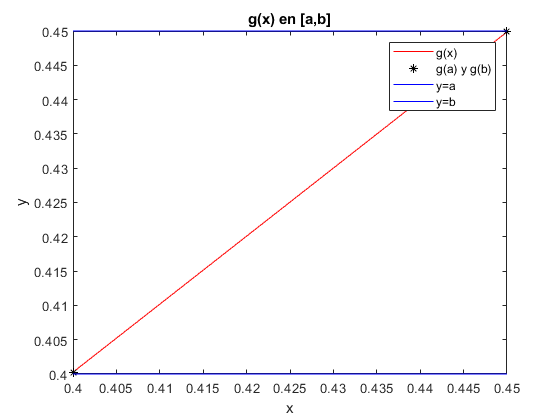

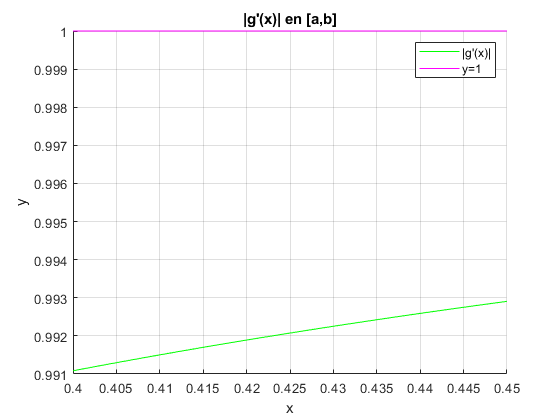

convergenciapfijo(g1, a, b)

Analizando las gráficas, se determina que el método es convergente, pues $g\left(\left\lbrack a,b\right\rbrack \right)\subseteq \left\lbrack a,b\right\rbrack$ y $\left|g^{\prime } \left(x\right)\right|<1,\;\forall x\in \left\lbrack a,b\right\rbrack$.

Por lo tanto, aplicamos el método a ambas ecuaciones, utilizando el mismo valor inicial que se utilizó para el Método de Newton-Raphson.

En este caso, se utilizará un valor mayor para maxiter, pues puede que el método tarde en converger.

maxiter = 500;

**Aproximación de **$a_1$

[a1PFijo, R1PFijo] = pfijo(g1, x0, tol, maxiter)

a1PFijo =    0.431817570908257


R1PFijo = 501×3 table
    Iteration           x*                     Er         
    _________    _________________    ____________________

        0                      0.4                       1
        1        0.400268300358698                       1
        2         0.40053421020086    0.000670301291553193
        3        0.400797753896155    0.000663887966095193
        4        0.401058955509447    0.000657547834869475
        5        0.401317838805666    0.000651279842286673
        6         0.40157442725459    0.000645082952180144
        7        0.401828744035518    0.000638956147376624
        8        0.402080812041862    0.000632898429250961
        9        0.402330653885639    0.000626908817319231
       10        0.402578291901879    0.000620986348826058
       11         0.40282374815294    0.000615130078351387
       12        0.403067044432743    0.000609339

**Aproximación de **$a_2$

[a2PFijo, R2PFijo] = pfijo(g2, x0, tol, maxiter)

a2PFijo =    0.422234044797071


R2PFijo = 501×3 table
    Iteration           x*                     Er         
    _________    _________________    ____________________

        0                      0.4                       1
        1        0.400186927811224                       1
        2        0.400372229437214    0.000467101242527875
        3        0.400555920481809    0.000462823373764463
        4        0.400738016373256    0.000458590262188125
        5        0.400918532366653    0.000454401339547123
        6        0.401097483546351    0.000450256046613291
        7        0.401274884828308    0.000446153833016601
        8        0.401450750962414    0.000442094157058654
        9        0.401625096534764     0.00043807648555735
       10        0.401797935969902    0.000434100293668709
       11        0.401969283533016     0.00043016506473589
       12        0.402139153332109    0.000426270

### Objetivo 3

A continuación, hallaremos las tensiones en cada cable de sustentación vertical para cumplir con el objetivo de hallar la tensión en los cables de sustentación vertical del área principal del puente.

**Aproximación de **$P_i$

PiPFijo = H*(sinh((-W/H)*0 + a1PFijo) - sinh(a2PFijo))

PiPFijo =      5.598373482665318e+02


### Objetivo 4

Finalmente, para cumplir el objetivo de comparar el valor hallado con lo propuesto por la literatura, se comparará el valor hallado en cada uno de los métodos con el valor esperado. Se hará uso del error relativo para lograr este propósito.

#### Resultado esperado

El resultado esperado para el valor de la tensión, que se asumirá como valor exacto, es el extraído del documento de Abdel-Ghaffar & Scanlan (1985): $P_i =572\ldotp 5\;\textrm{kips}$.

PiExacto = 572.5;

#### Método de la Bisección

ErBiseccion = errorrelativo(PiExacto, PiBiseccion)

ErBiseccion =      6.235043337686693e-04


Se observa que el resultado aproxima al valor exacto con 3 cifras significativas.

#### Método de Newton-Raphson

ErNewtonRaphson = errorrelativo(PiExacto, PiNewtonRaphson)

ErNewtonRaphson =      6.233222773008537e-04


Se obtiene un error similar al del Método de la Bisección. Igualmente, el resultado aproxima al valor exacto con 3 cifras significativas.

#### Método del Punto Fijo

ErPFijo = errorrelativo(PiExacto, PiPFijo)

ErPFijo =    0.022118168966757


A pesar de tener más de 10 veces el número de iteraciones que los otros métodos, el Método del Punto Fijo con el despeje utilizado da tan solo 2 cifras significativas, por lo que es una aproximación poco confiable.

## Discusión

Como se pudo observar, el valor de la tensión calculado es bastante bueno, considerando que se utilizó una  aproximación parabólica para el cable principal. 

# Conclusiones

El análisis del comportamiento de los puentes colgantes es muy exhaustivo; sin embargo, es de mucha importancia para evitar accidentes como derrumbamientos. Existen muchos factores que a considerar al realizar un estudio de este tipo, por lo que emplear un método numérico efectivo es necesario para la precisión y exactitud de los resultados. Como se pudo observar, el valor de la tensión calculado es bastante bueno, considerando que se utilizó una  aproximación parabólica para el cable principal. 

En un contexto cercano a la realidad, en el actual estudio no se consideraron otras anomalías como lo son desastres naturales, durabilidad de los materiales empleados en la construcción del puente y fuerza ejercida por la circulación masiva en el puente. 

# Bibliografía 

- Abdel-Ghaffar, A. M., & Scanlan, R. H. (1985). Ambient vibration studies of golden gate bridge: I. Suspended structure. *Journal of Engineering Mechanics*, *111*(4), 463-482.

- Cao, H., Zhou, Y. L., Chen, Z., & Abdel Wahab, M. (2017). Form-finding analysis of suspension bridges using an explicit iterative approach. *Structural Engineering and Mechanics*, *62*(1), 85-95.

- Cáceres, J., De Rojas, G., Huamaní, R., Torres, J., & Zuloeta, L. (2021). Ecuación de la catenaria para calcular las fuerzas internas de los cables verticales de un puente colgante.

- Zhang, W. M., Li, T., Shi, L. Y., Liu, Z., & Qian, K. R. (2018). An iterative calculation method for hanger tensions and the cable shape of a suspension bridge based on the catenary theory and finite element method. *Advances in Structural Engineering*, *22*(7), 1566-1578.

## Anexos

### Anexo 1: Datos estructurales del puente Golden Gate (Abdel-Ghaffar & Scanlan, 1985)

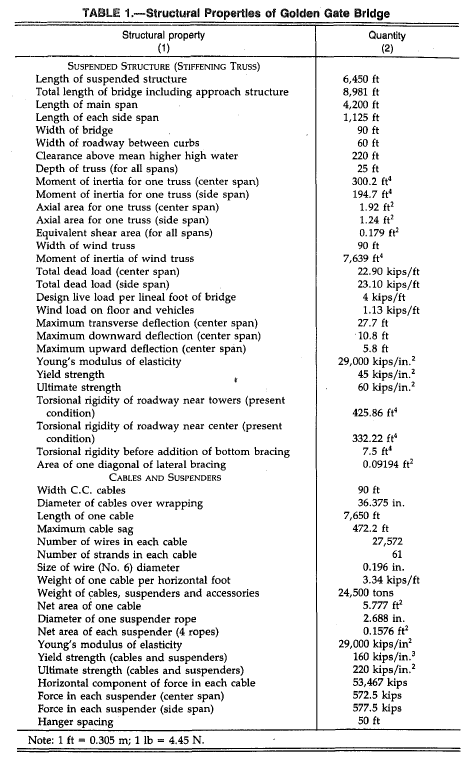

# Funciones Matlab

function [R, z]=biseccion(f, a, b, tol, maxiter)
    if f(a) * f(b) > 0
        z = [];
        fprintf("No se puede asegurar que existe una raíz en este intervalo.");
        return;
    end
    c = (a + b) / 2;
    error = (b - a) / 2;
    n = 0;
    z = [n a b c f(a) f(b) f(c) error];
    while error > tol && n < maxiter
        n = n + 1;
        if f(a) * f(c) <= 0
            b = c;
        else
            a = c;  
        end
        c = (a + b) / 2;
        error = (b - a) / 2;
        z = [z; n a b c f(a) f(b) f(c) error];
    end
    z = array2table(z, 'VariableNames', {'Iteration', 'a', 'b', 'c', 'f(a)', 'f(b)', 'f(c)', 'Ea'});
    R = z.c(end);
end
function [R,z]=newtonraphson(f, x0, tol, maxiter)
    syms x;
    df = diff(f(x));
    f_prim = inline(subs(df), 'x');
    n = 0;
    error = 1;
    z = [n x0 error];
    while error > tol && n < maxiter
        n = n + 1;
        x1 = x0 - (f(x0) / f_prim(x0));
        z = [z; n x1 error];
        error = abs(x1 - x0) / abs(x1);
        x0 = x1;
    end
    z = array2table(z, 'VariableNames', {'Iteration', 'x*', 'Er'});
    R = z.("x*")(end);
end
function [R,z]=pfijo(g, x0, tol, maxiter)
    k = 0;
    error = 1;
    z = [k x0 error];
    while k < maxiter && error > tol
        k = k + 1;
        x1 = g(x0);
        z = [z; k x1 error];
        error = abs(x1 - x0) / abs(x1);
        x0 = x1;
    end
    z = array2table(z, 'VariableNames', {'Iteration', 'x*', 'Er'});
    R = z.("x*")(end);
end
function convergenciapfijo(g, a, b)
    % se asume continua en [a,b] y derivable en (a,b)

    % g([a,b]) C [a,b]
    figure(1)
    grid on;
    hold off;
    xs = linspace(a, b, 100);
    plot(xs, g(xs), 'r', [a b], [g(a) g(b)], '*k');
    hold on;
    y1 = @(x) (a .* x.^0);
    y2 = @(x) (b .* x.^0);
    plot(xs, y1(xs), 'b');
    plot(xs, y2(xs), 'b');
    title("g(x) en [a,b]");
    xlabel("x");
    ylabel("y");
    legend("g(x)", "g(a) y g(b)", "y=a", "y=b");

    % |g'(x)| < 1 para x in [a,b]
    figure(2)
    grid on;
    hold on;
    syms x;
    g_diff = diff(g(x));
    g_diff_fun = inline(subs(g_diff), 'x');
    plot(xs, abs(g_diff_fun(xs)), 'g');
    y3 = @(x) (1 .* x.^0);
    plot(xs, y3(xs), 'm');
    legend("|g'(x)|", "y=1");
    xlabel("x");
    ylabel("y");
    title("|g'(x)| en [a,b]");
end
function E=errorrelativo(A, a)
    E = abs(A-a)/abs(A);
end